# 03E. Bifurcation for two-variable systems

## Mingyang Lu

## 1/7/2024

## Generating bifurcation diagram

Here, we consider the same toggle switch circuit but with slightly modified parameters. The rate equations have two variables $X\;$and $Y$ and two parameters $g_X \;$and $k$.


$$\begin{cases} \frac{dX}{dt} = f_X(X, Y, g_X, k) = 5 + g_X\frac{1}{1+(Y/100)^4} - kX \\
              \frac{dY}{dt} = f_Y(X, Y, g_X, k) = 5 + 50\frac{1}{1+(X/100)^4} - kY  \end{cases}$$


We will identify bifurcation diagrams by varying either $g_X \;$or $k$.

### Saddle-node bifurcation

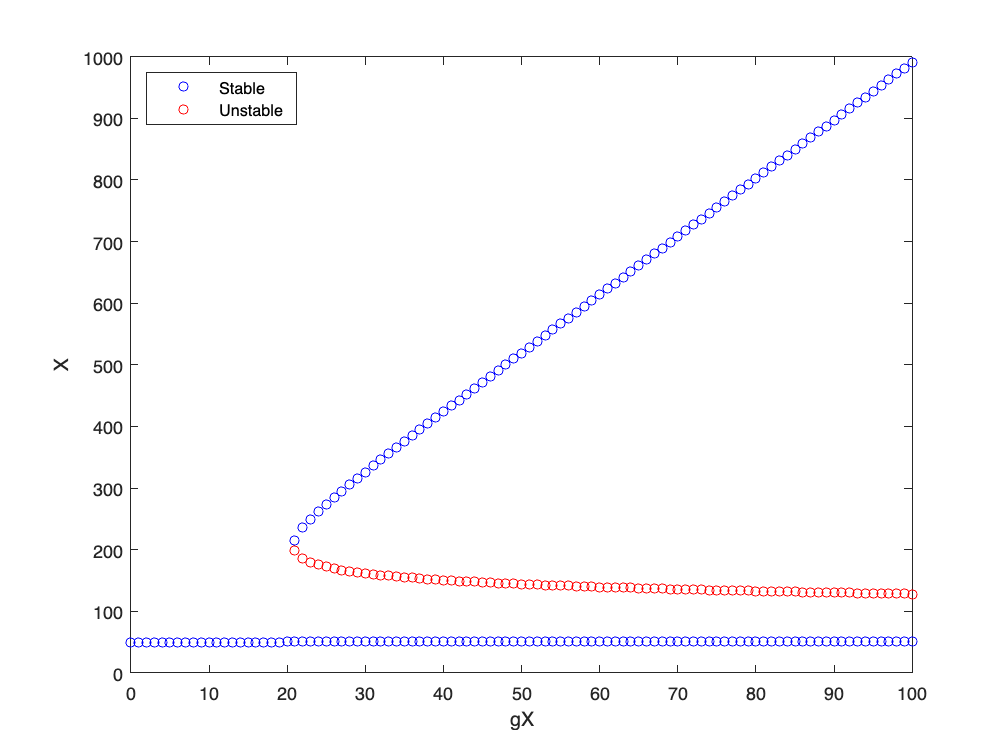

X_range = [0, 1000];
Y_range = [0, 1000];
k = 0.1;

% Initialize a large matrix to save up to 1000 steady states
max_num_points = 1000;
ss_all = NaN(max_num_points, 4);

i = 1;
% Iterate over various gX
for gX = 0:1:100
    ss = find_steady_states(gX, k, X_range, Y_range);
    % Iterate over any steady state and save it
    for j = 1:size(ss, 1)
        ss_all(i, 1) = gX;
        ss_all(i, 2:end) = ss(j, :);
        i = i + 1;
    end
end
% Obtain the trimmed matrix for the final results
ss_all = ss_all(1:(i-1), :);

% Plot the results
gscatter(ss_all(:, 1), ss_all(:, 2), ss_all(:,4), 'br', 'o', 5);
xlabel('gX');
ylabel('X');
xlim([0, 100]);
ylim([0, 1000]);

% Create legend
legend('Stable', 'Unstable', 'Location', 'northwest');

### Pitchfork bifurcation[¶](http://localhost:8888/notebooks/03E.ipynb#Pitchfork-bifurcation)

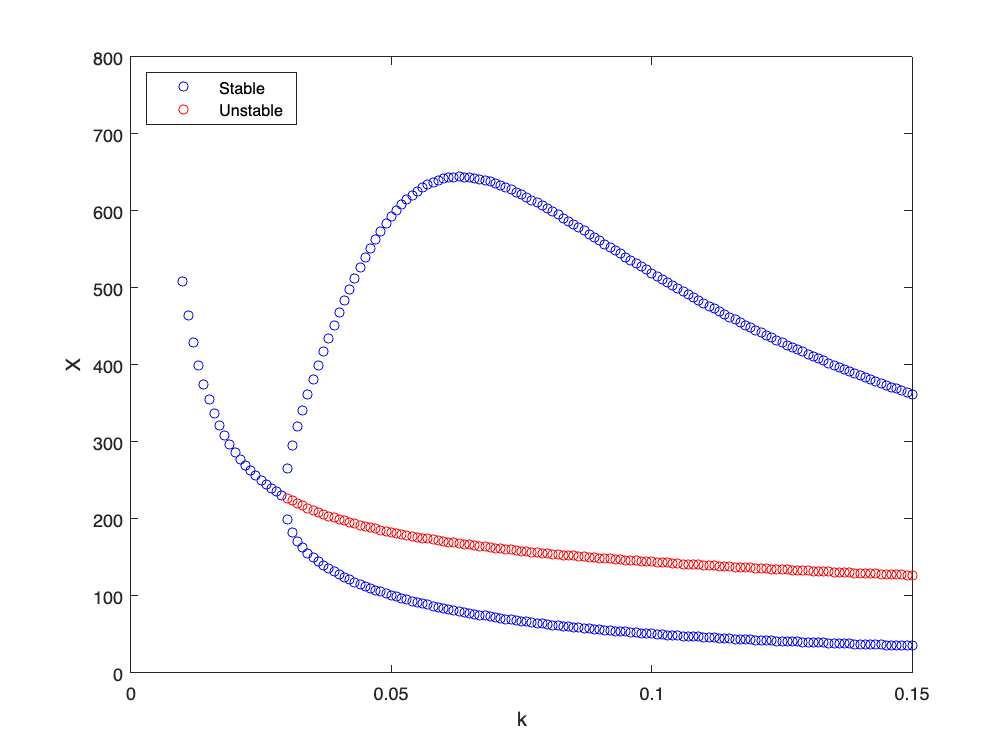

X_range = [0, 1000];
Y_range = [0, 1000];
gX = 50;

% Initialize a large matrix to save up to 1000 steady states
max_num_points = 1000;
ss_all = NaN(max_num_points, 4);

i = 1;
% Iterate over various gX
for k = 0.01:0.001:0.15
    ss = find_steady_states(gX, k, X_range, Y_range);
    % Iterate over any steady state and save it
    for j = 1:size(ss, 1)
        ss_all(i, 1) = k;
        ss_all(i, 2:end) = ss(j, :);
        i = i + 1;
    end
end
% Obtain the trimmed matrix for the final results
ss_all = ss_all(1:(i-1), :);

% Plot the results
gscatter(ss_all(:, 1), ss_all(:, 2), ss_all(:,4), 'br', 'o', 5);
xlabel('k');
ylabel('X');
xlim([0, 0.15]);
ylim([0, 800]);

% Create legend
legend('Stable', 'Unstable', 'Location', 'northwest');

### Define MATLAB functions

1. Function for dx/dt

function result = fx(X, Y, gX, k)
result = 5 + gX ./ (1 + (Y ./ 100).^4) - k .* X;
end

2. Function for dy/dt


function result = fy(X, Y, gX, k)
result = 5 + 50 ./ (1 + (X ./ 100).^4) - k .* Y;
end

3. X nullcline 


function results = null_fx(gX, k, X_range, Y_range)
    Y_all = linspace(Y_range(1), Y_range(2), 1000);
    X_all = (5 + gX ./ (1 + (Y_all / 100) .^ 4)) / k;
    ind = find((X_all - X_range(1)) .* (X_all - X_range(2)) <= 0);
    results = [X_all(ind)', Y_all(ind)'];
end

4. Y nullcline 


function results = null_fy(gX, k, X_range, Y_range)
    X_all = linspace(X_range(1), X_range(2), 1000);
    Y_all = (5 + 50 ./ (1 + (X_all / 100) .^ 4)) / k;
    ind = find((Y_all - Y_range(1)) .* (Y_all - Y_range(2)) <= 0);
    results = [X_all(ind)', Y_all(ind)'];
end

5. Find intersection of two line segments

function intersection = find_intersection(lineA, lineB, nA, nB)
    dAX = lineA(nA + 1, 1) - lineA(nA, 1);
    dAY = lineA(nA + 1, 2) - lineA(nA, 2);

    dBX = lineB(nB + 1, 1) - lineB(nB, 1);
    dBY = lineB(nB + 1, 2) - lineB(nB, 2);

    dABX = lineB(nB, 1) - lineA(nA, 1);
    dABY = lineB(nB, 2) - lineA(nA, 2);

    d = dAX * dBY - dAY * dBX;

    alpha = (dABX * dBY - dABY * dBX) / d;
    beta = (dABX * dAY - dABY * dAX) / d;

    % check whether there is an intersection in between
    if (0 <= alpha && alpha <= 1) && (0 <= beta && beta <= 1)
        intersection = [(1 - alpha) * lineA(nA, 1) + alpha * lineA(nA + 1, 1), ...
                        (1 - alpha) * lineA(nA, 2) + alpha * lineA(nA + 1, 2), ...
                        1];
        % 1st and 2nd elements: X & Y
        % 3rd element: 1 means found, 0 means not found
    else
        intersection = [alpha, beta, 0];
        % 1st and 2nd elements: alpha & beta
    end
end

6. Search and find all intersections between two curves


function results = find_intersection_all_fast(lineA, lineB, dxdt, dydt)
    small = 1e-3; % used to allow some tolerance of numerical errors in detecting sign flipping
    lineA_ind = find(dydt .* [dydt(2:end); NaN] <= small);
    lineB_ind = find(dxdt .* [dxdt(2:end); NaN] <= small);
    
    results = zeros(1000, 2);
    ind = 0;
    for i = 1:size(lineA_ind)
        ind_i = lineA_ind(i);
        for j = 1:size(lineB_ind)
            ind_j = lineB_ind(j);
            intersection = find_intersection(lineA, lineB, ind_i, ind_j);
            if (intersection(3) == 1)
                ind = ind + 1;
                results(ind,:) = intersection(1:2);
            end
        end
    end
    results = results(1:ind,:);
end

7. Compute the local stability of a steady state

function stability = stability_v2(func_fx, func_fy, gX, k, ss)
    delta = 0.001;
    delta2 = delta * 2;
    func_fx_current = func_fx(ss(1), ss(2), gX, k);
    func_fy_current = func_fy(ss(1), ss(2), gX, k);
    
    dfxdx = (func_fx(ss(1) + delta, ss(2), gX, k) - func_fx_current) / delta2;
    dfxdy = (func_fx(ss(1), ss(2) + delta, gX, k) - func_fx_current) / delta2;
    dfydx = (func_fy(ss(1) + delta, ss(2), gX, k) - func_fy_current) / delta2;
    dfydy = (func_fy(ss(1), ss(2) + delta, gX, k) - func_fy_current) / delta2;
    
    jacobian = [dfxdx, dfydx; dfxdy, dfydy];
    lambda_values = eig(jacobian);
    
    if any(imag(lambda_values(1)))
        if real(lambda_values(1)) < 0
            stability = 4;  % stable spiral
        else
            stability = 5;  % unstable spiral
        end
    else
        if lambda_values(1) < 0 && lambda_values(2) < 0
            stability = 1;  % stable
        elseif lambda_values(1) >= 0 && lambda_values(2) >= 0
            stability = 2;  % unstable
        else
            stability = 3;  % saddle
        end
    end
end

8. A unified functon to find all steady states and their local stability.


function ss_with_stability = find_steady_states(gX, k, X_range, Y_range)
    line_1 = null_fx(gX, k, X_range, Y_range);
    line_2 = null_fy(gX, k, X_range, Y_range);
    
    dxdt = fx(line_2(:, 1), line_2(:, 2), gX, k);  % dX/dt along the nullcline dY/dt = 0
    dydt = fy(line_1(:, 1), line_1(:, 2), gX, k);  % dY/dt along the nullcline dX/dt = 0
    
    ss = find_intersection_all_fast(line_1, line_2, dxdt, dydt);
    
    ss_with_stability = zeros(size(ss, 1), 3);
    for i = 1:size(ss, 1)
        ss_with_stability(i, :) = [ss(i, :), stability_v2(@fx, @fy, gX, k, ss(i, :))];
    end
end